# Machine Learning: Programming Exercise 7

## *K*-Means Clustering and Principal Component Analysis

In this exercise, you will implement the *K*-means clustering algorithm and apply it to compress an image. In the second part, you will use principal component analysis to find a low-dimensional representation of face images.

### Files needed for this exercise

- `ex7.mlx` - MATLAB Live Script that steps you through the exercise

- `ex7data1.mat` - Example Dataset for PCA

- `ex7data2.mat` - Example Dataset for K-means

- `ex7faces.mat` - Faces Dataset

- bird small.png - Example Image

- `displayData.m` - Displays 2D data stored in a matrix

- `drawLine.m` - Draws a line over an exsiting figure

- `plotDataPoints.m` - Initialization for K-means centroids

- `plotProgresskMeans.m` - Plots each step of K-means as it proceeds

- `runkMeans.m` - Runs the K-means algorithm

- `submit.m` - Submission script that sends your solutions to our servers

- *`pca.m` - Perform principal component analysis

- *`projectData.m` - Projects a data set into a lower dimensional space

- *`recoverData.m` - Recovers the original data from the projection

- *`findClosestCentroids.m` - Find closest centroids (used in K-means)

- *`computeCentroids.m` - Compute centroid means (used in K-means)

- *`kMeansInitCentroids.m` - Initialization for K-means centroids

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex7' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. *K*-Means Clustering

In this this exercise, you will implement the *K*-means algorithm and use it for image compression. You will first start on an example 2D dataset that will help you gain an intuition of how the *K*-means algorithm works. After that, you wil use the *K*-means algorithm for image compression by reducing the number of colors that occur in an image to only those that are most common in that image.

### 1.1 Implementing *K*-means

The K-means algorithm is a method to automatically cluster similar data examples together. Concretely, you are given a training set $\{x^{(1)},\ldots x^{(m)}\}$ (where $x^{(i)}\in \mathbb{R}^n$), and want to group the data into a few cohesive 'clusters'. The intuition behind *K*-means is an iterative procedure that starts by guessing the initial centroids, and then refines this guess by repeatedly assigning examples to their closest centroids and then recomputing the centroids based on the assignments.

    The *K*-means algorithm is as follows:

The inner-loop of the algorithm repeatedly carries out two steps: 

- Assigning each training example $x^{(i)}$ to its closest centroid

- Recomputing the mean of each centroid using the points assigned to it. 

The *K*-means algorithm will always converge to some final set of means for the centroids. Note that the converged solution may not always be ideal and depends on the initial setting of the centroids. Therefore, in practice the K-means algorithm is usually run a few times with dierent random initializations. One way to choose between these different solutions from different random initializations is to choose the one with the lowest cost function value (distortion). You will implement the two phases of the K-means algorithm separately in the next sections.

#### 1.1.1 Finding closest centroids

In the 'cluster assignment' phase of the *K*-means algorithm, the algorithm assigns every training example $x^{(i)}$ to its closest centroid, given the current positions of centroids. Specically, for every example $i$ we set 


$$c^{(i)} :=j \quad\text{that minimizes}\quad\left||x^{(i)}-\mu_j\right||^2,$$


where $c^{(i)}$ is the index of the centroid that is closest to $x^{(i)}$, and $\mu_j$ is the position (value) of the $j$-th centroid. Note that $c^{(i)}$ corresponds to `idx(i)` in the starter code.

    Your task is to complete the code in `findClosestCentroids.m`. This function takes the data matrix `X` and the locations of all centroids inside centroids and should output a one-dimensional array `idx` that holds the index (a value in $\{1,\ldots,K\}$, where $K$ is total number of centroids) of the closest centroid to every training example. You can implement this using a loop over every training example and every centroid. 

    Once you have completed the code in `findClosestCentroids.m`, the code below will run your code and you should see the output `[1 3 2]` corresponding to the centroid assignments for the first 3 examples.

% Load an example dataset that we will be using
load('ex7data2.mat');

% Select an initial set of centroids
K = 3; % 3 Centroids
initial_centroids = [3 3; 6 2; 8 5];

% Find the closest centroids for the examples using the initial_centroids
idx = findClosestCentroids(X, initial_centroids);

a =     1.8421
    4.6076


mn = 3.9251

b =      6
     2


sm = 24.0877

b =      8
     5


sm = 38.0740

a =     5.6586
    4.8000


mn = 10.3079

b =      6
     2


sm = 7.9564

mn = 7.9564

idx =      1
     2
     1
     1
     1
     1
     1
     1
     1
     1


b =      8
     5


sm = 5.5222

mn = 5.5222

idx =      1
     3
     1
     1
     1
     1
     1
     1
     1
     1


a =     6.3526
    3.2909


mn = 11.3244

b =      6
     2


sm = 1.7906

mn = 1.7906

idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b =      8
     5


sm = 5.6352

a =     2.9040
    4.6122


mn = 2.6084

b =      6
     2


sm = 16.4087

b =      8
     5


sm = 26.1194

a =     3.2320
    4.9399


mn = 3.8170

b =      6
     2


sm = 16.3049

b =      8
     5


sm = 22.7376

a =     1.2479
    4.9327


mn = 6.8050

b =      6
     2


sm = 31.1828

b =      8
     5


sm = 45.5951

a =     1.9762
    4.4349


mn = 3.1071

b =      6
     2


sm = 22.1197

b =      8
     5


sm = 36.6055

a =     2.2345
    5.0555


mn = 4.8109

b =      6
     2


sm = 23.5146

b =      8
     5


sm = 33.2436

a =     2.9834
    4.8405


mn = 3.3876

b =      6
     2


sm = 17.1681

b =      8
     5


sm = 25.1917

a =     2.9797
    4.8067


mn = 3.2646

b =      6
     2


sm = 16.9998

b =      8
     5


sm = 25.2407

a =     2.1150
    5.3737


mn = 6.4179

b =      6
     2


sm = 26.4756

b =      8
     5


sm = 34.7733

a =     2.1217
    5.2085


mn = 5.6491

b =      6
     2


sm = 25.3360

b =      8
     5


sm = 34.5980

a =     1.5144
    4.7700


mn = 5.3402

b =      6
     2


sm = 27.7941

b =      8
     5


sm = 42.1165

a =     2.1698
    5.2744


mn = 5.8619

b =      6
     2


sm = 25.3919

b =      8
     5


sm = 34.0666

a =     0.4185
    4.8831


mn = 10.2102

b =      6
     2


sm = 39.4653

b =      8
     5


sm = 57.4924

a =     2.4705
    4.8042


mn = 3.5354

b =      6
     2


sm = 20.3206

b = 2×1
     8
     5


sm = 30.6133

a = 2×1
    4.0607
    4.9950


mn = 5.1052

b = 2×1
     6
     2


sm = 12.7312

b = 2×1
     8
     5


sm = 15.5182

a = 2×1
    3.0071
    4.6790


mn = 2.8190

b = 2×1
     6
     2


sm = 16.1344

b = 2×1
     8
     5


sm = 25.0322

a = 2×1
    0.6663
    4.8719


mn = 8.9500

b = 2×1
     6
     2


sm = 36.6958

b = 2×1
     8
     5


sm = 53.7992

a = 2×1
    3.1622
    4.8366


mn = 3.3993

b = 2×1
     6
     2


sm = 16.0994

b = 2×1
     8
     5


sm = 23.4311

a = 2×1
    0.5116
    4.9105


mn = 9.8425

b = 2×1
     6
     2


sm = 38.5942

b = 2×1
     8
     5


sm = 56.0848

a = 2×1
    3.1343
    4.9618


mn = 3.8666

b = 2×1
     6
     2


sm = 16.9845

b = 2×1
     8
     5


sm = 23.6767

a = 2×1
    2.0497
    5.6241


mn = 7.7891

b = 2×1
     6
     2


sm = 28.7389

b = 2×1
     8
     5


sm = 35.7951

a = 2×1
    0.6658
    5.2440


mn = 10.4839

b = 2×1
     6
     2


sm = 38.9769

b = 2×1
     8
     5


sm = 53.8496

a = 2×1
    1.0173
    4.8447


mn = 7.3341

b = 2×1
     6
     2


sm = 32.9196

b = 2×1
     8
     5


sm = 48.7819

a = 2×1
    2.1789
    5.2976


mn = 5.9531

b = 2×1
     6
     2


sm = 25.4746

b = 2×1
     8
     5


sm = 33.9733

a = 2×1
    2.8596
    5.2604


mn = 5.1292

b = 2×1
     6
     2


sm = 20.4923

b = 2×1
     8
     5


sm = 26.4913

a = 2×1
    1.3088
    5.3016


mn = 8.1574

b = 2×1
     6
     2


sm = 32.9076

b = 2×1
     8
     5


sm = 44.8628

a = 2×1
    0.9925
    5.0157


mn = 8.0929

b = 2×1
     6
     2


sm = 34.1690

b = 2×1
     8
     5


sm = 49.1048

a = 2×1
    1.4037
    4.5753


mn = 5.0296

b = 2×1
     6
     2


sm = 27.7578

b = 2×1
     8
     5


sm = 43.6912

a = 2×1
    2.6605
    5.1962


mn = 4.9387

b = 2×1
     6
     2


sm = 21.3684

b = 2×1
     8
     5


sm = 28.5491

a = 2×1
    2.8000
    5.1153


mn = 4.5144

b = 2×1
     6
     2


sm = 19.9451

b = 2×1
     8
     5


sm = 27.0537

a = 2×1
    2.0700
    4.6847


mn = 3.7031

b = 2×1
     6
     2


sm = 22.6527

b = 2×1
     8
     5


sm = 35.2649

a = 2×1
    3.2977
    5.5921


mn = 6.8073

b = 2×1
     6
     2


sm = 20.2055

b = 2×1
     8
     5


sm = 22.4626

a = 2×1
    1.8930
    4.8904


mn = 4.7992

b = 2×1
     6
     2


sm = 25.2222

b = 2×1
     8
     5


sm = 37.3077

a = 2×1
    2.5598
    5.2640


mn = 5.3193

b = 2×1
     6
     2


sm = 22.4883

b = 2×1
     8
     5


sm = 29.6651

a = 2×1
    1.1535
    4.6787


mn = 6.2273

b = 2×1
     6
     2


sm = 30.6634

b = 2×1
     8
     5


sm = 46.9773

a = 2×1
    2.2515
    5.4450


mn = 6.5383

b = 2×1
     6
     2


sm = 25.9192

b = 2×1
     8
     5


sm = 33.2432

a = 2×1
    2.2096
    4.9147


mn = 4.2908

b = 2×1
     6
     2


sm = 22.8625

b = 2×1
     8
     5


sm = 33.5360

a = 2×1
    1.5914
    4.8321


mn = 5.3408

b = 2×1
     6
     2


sm = 27.4565

b = 2×1
     8
     5


sm = 41.0981

a = 2×1
    1.6784
    5.2690


mn = 6.8952

b = 2×1
     6
     2


sm = 29.3630

b = 2×1
     8
     5


sm = 40.0353

a = 2×1
    2.5915
    4.9259


mn = 3.8761

b = 2×1
     6
     2


sm = 20.1791

b = 2×1
     8
     5


sm = 29.2575

a = 2×1
    2.8100
    5.5385


mn = 6.4801

b = 2×1
     6
     2


sm = 22.6973

b = 2×1
     8
     5


sm = 27.2265

a = 2×1
    0.9531
    5.5804


mn = 10.8480

b = 2×1
     6
     2


sm = 38.2901

b = 2×1
     8
     5


sm = 49.9954

a = 2×1
    1.5178
    5.0384


mn = 6.3520

b = 2×1
     6
     2


sm = 29.3222

b = 2×1
     8
     5


sm = 42.0210

a = 2×1
    3.2311
    5.7843


mn = 7.8057

b = 2×1
     6
     2


sm = 21.9875

b = 2×1
     8
     5


sm = 23.3571

a = 2×1
    2.5418
    4.8110


mn = 3.4896

b = 2×1
     6
     2


sm = 19.8608

b = 2×1
     8
     5


sm = 29.8277

a = 2×1
    3.8142
    4.7353


mn = 3.6741

b = 2×1
     6
     2


sm = 12.2593

b = 2×1
     8
     5


sm = 17.5908

a = 2×1
    1.6850
    4.5964


mn = 4.2779

b = 2×1
     6
     2


sm = 25.3611

b = 2×1
     8
     5


sm = 40.0426

a = 2×1
    2.1778
    4.8615


mn = 4.1414

b = 2×1
     6
     2


sm = 22.7978

b = 2×1
     8
     5


sm = 33.9175

a = 2×1
    1.8173
    5.1333


mn = 5.9498

b = 2×1
     6
     2


sm = 27.3125

b = 2×1
     8
     5


sm = 38.2432

a = 2×1
    1.8578
    4.8696


mn = 4.8002

b = 2×1
     6
     2


sm = 25.3928

b = 2×1
     8
     5


sm = 37.7440

a = 2×1
    3.0308
    5.2406


mn = 5.0211

b = 2×1
     6
     2


sm = 19.3172

b = 2×1
     8
     5


sm = 24.7504

a = 2×1
    2.9266
    5.0967


mn = 4.4015

b = 2×1
     6
     2


sm = 19.0353

b = 2×1
     8
     5


sm = 25.7489

a = 2×1
    3.4349
    5.3408


mn = 5.6685

b = 2×1
     6
     2


sm = 17.7406

b = 2×1
     8
     5


sm = 20.9560

a = 2×1
    3.2037
    4.8592


mn = 3.4983

b = 2×1
     6
     2


sm = 15.9948

b = 2×1
     8
     5


sm = 23.0246

a = 2×1
    0.1051
    4.7292


mn = 11.3703

b = 2×1
     6
     2


sm = 42.1980

b = 2×1
     8
     5


sm = 62.4025

a = 2×1
    1.4060
    5.0664


mn = 6.8108

b = 2×1
     6
     2


sm = 30.5076

b = 2×1
     8
     5


sm = 43.4855

a = 2×1
    2.2419
    4.9245


mn = 4.2783

b = 2×1
     6
     2


sm = 22.6762

b = 2×1
     8
     5


sm = 33.1620

a = 2×1
    1.3668
    5.2616


mn = 7.7823

b = 2×1
     6
     2


sm = 32.1048

b = 2×1
     8
     5


sm = 44.0680

a = 2×1
    1.7073
    4.0423


mn = 2.7576

b = 2×1
     6
     2


sm = 22.5987

b = 2×1
     8
     5


sm = 40.5158

a = 2×1
    1.9191
    5.5785


mn = 7.8169

b = 2×1
     6
     2


sm = 29.4593

b = 2×1
     8
     5


sm = 37.3120

a = 2×1
    1.6016
    4.6445


mn = 4.6601

b = 2×1
     6
     2


sm = 26.3397

b = 2×1
     8
     5


sm = 41.0663

a = 2×1
    0.3796
    5.2619


mn = 11.9827

b = 2×1
     6
     2


sm = 42.2288

b = 2×1
     8
     5


sm = 58.1386

a = 2×1
    2.0213
    4.4127


mn = 2.9534

b = 2×1
     6
     2


sm = 21.6507

b = 2×1
     8
     5


sm = 36.0893

a = 2×1
    1.1204
    5.2088


mn = 8.4118

b = 2×1
     6
     2


sm = 34.1073

b = 2×1
     8
     5


sm = 47.3729

a = 2×1
    2.2690
    4.6182


mn = 3.1529

b = 2×1
     6
     2


sm = 20.7752

b = 2×1
     8
     5


sm = 32.9900

a = 2×1
   -0.2451
    5.7402


mn = 18.0395

b = 2×1
     6
     2


sm = 52.9907

b = 2×1
     8
     5


sm = 68.5300

a = 2×1
    2.1286
    5.0115


mn = 4.8055

b = 2×1
     6
     2


sm = 24.0570

b = 2×1
     8
     5


sm = 34.4737

a = 2×1
    1.8442
    5.0315


mn = 5.4630

b = 2×1
     6
     2


sm = 26.4609

b = 2×1
     8
     5


sm = 37.8949

a = 2×1
    2.3256
    4.7487


mn = 3.5127

b = 2×1
     6
     2


sm = 21.0566

b = 2×1
     8
     5


sm = 32.2622

a = 2×1
    1.5233
    4.8792


mn = 5.7118

b = 2×1
     6
     2


sm = 28.3300

b = 2×1
     8
     5


sm = 41.9617

a = 2×1
    1.0229
    5.0105


mn = 7.9513

b = 2×1
     6
     2


sm = 33.8352

b = 2×1
     8
     5


sm = 48.6807

a = 2×1
    1.8538
    5.0075


mn = 5.3439

b = 2×1
     6
     2


sm = 26.2360

b = 2×1
     8
     5


sm = 37.7755

a = 2×1
    2.2032
    4.9452


mn = 4.4185

b = 2×1
     6
     2


sm = 23.0896

b = 2×1
     8
     5


sm = 33.6057

a = 2×1
    1.2010
    4.5783


mn = 5.7274

b = 2×1
     6
     2


sm = 29.6780

b = 2×1
     8
     5


sm = 46.4042

a = 2×1
    1.0206
    4.6299


mn = 6.5745

b = 2×1
     6
     2


sm = 31.7106

b = 2×1
     8
     5


sm = 48.8486

a = 2×1
    1.6049
    5.1366


mn = 6.5114

b = 2×1
     6
     2


sm = 29.1551

b = 2×1
     8
     5


sm = 40.9156

a = 2×1
    0.4765
    5.1354


mn = 10.9279

b = 2×1
     6
     2


sm = 40.3398

b = 2×1
     8
     5


sm = 56.6218

a = 2×1
    0.3639
    4.7333


mn = 9.9534

b = 2×1
     6
     2


sm = 39.2365

b = 2×1
     8
     5


sm = 58.3809

a = 2×1
    0.3132
    5.5469


mn = 13.7058

b = 2×1
     6
     2


sm = 44.9205

b = 2×1
     8
     5


sm = 59.3861

a = 2×1
    2.2866
    5.0077


mn = 4.5396

b = 2×1
     6
     2


sm = 22.8351

b = 2×1
     8
     5


sm = 32.6424

a = 2×1
    2.1546
    5.4628


mn = 6.7802

b = 2×1
     6
     2


sm = 26.7783

b = 2×1
     8
     5


sm = 34.3829

a = 2×1
    2.0529
    4.7796


mn = 4.0640

b = 2×1
     6
     2


sm = 23.3058

b = 2×1
     8
     5


sm = 35.4168

a = 2×1
    4.8880
    5.5067


mn = 9.8483

b = 2×1
     6
     2


sm = 13.5334

b = 2×1
     8
     5


sm = 9.9410

a = 2×1
    2.4030
    5.0815


mn = 4.6889

b = 2×1
     6
     2


sm = 22.4335

b = 2×1
     8
     5


sm = 31.3325

a = 2×1
    2.5687
    5.2069


mn = 5.0563

b = 2×1
     6
     2


sm = 22.0579

b = 2×1
     8
     5


sm = 29.5419

a = 2×1
    1.8298
    4.5966


mn = 3.9185

b = 2×1
     6
     2


sm = 24.1331

b = 2×1
     8
     5


sm = 38.2346

a = 2×1
    0.5485
    5.0267


mn = 10.1177

b = 2×1
     6
     2


sm = 38.8805

b = 2×1
     8
     5


sm = 55.5263

a = 2×1
    3.1711
    5.5946


mn = 6.7615

b = 2×1
     6
     2


sm = 20.9242

b = 2×1
     8
     5


sm = 23.6719

a = 2×1
    3.0420
    5.0076


mn = 4.0322

b = 2×1
     6
     2


sm = 17.7952

b = 2×1
     8
     5


sm = 24.5816

a = 2×1
    2.4043
    5.0259


mn = 4.4590

b = 2×1
     6
     2


sm = 22.0851

b = 2×1
     8
     5


sm = 31.3128

a = 2×1
    0.1778
    5.2977


mn = 13.2438

b = 2×1
     6
     2


sm = 44.7721

b = 2×1
     8
     5


sm = 61.2749

a = 2×1
    2.6143
    5.2229


mn = 5.0899

b = 2×1
     6
     2


sm = 21.8500

b = 2×1
     8
     5


sm = 29.0556

a = 2×1
    2.3010
    4.9724


mn = 4.3788

b = 2×1
     6
     2


sm = 22.5177

b = 2×1
     8
     5


sm = 32.4796

a = 2×1
    3.9078
    5.0946


mn = 5.2116

b = 2×1
     6
     2


sm = 13.9542

b = 2×1
     8
     5


sm = 16.7551

a = 2×1
    2.0567
    5.2339


mn = 5.8802

b = 2×1
     6
     2


sm = 26.0078

b = 2×1
     8
     5


sm = 35.3775

a = 2×1
    1.3813
    5.0019


mn = 6.6279

b = 2×1
     6
     2


sm = 30.3438

b = 2×1
     8
     5


sm = 43.8067

a = 2×1
    1.1607
    4.6773


mn = 6.1961

b = 2×1
     6
     2


sm = 30.5862

b = 2×1
     8
     5


sm = 46.8796

a = 2×1
    1.7282
    5.3603


mn = 7.1885

b = 2×1
     6
     2


sm = 29.5399

b = 2×1
     8
     5


sm = 39.4655

a = 2×1
    3.2036
    0.7222


mn = 5.2298

b = 2×1
     6
     2


sm = 9.4526

b = 2×1
     8
     5


sm = 41.3048

a = 2×1
    3.0619
    1.5719


mn = 2.0432

b = 2×1
     6
     2


sm = 8.8155

b = 2×1
     8
     5


sm = 36.1363

a = 2×1
    4.0171
    1.1607


mn = 4.4176

b = 2×1
     6
     2


sm = 4.6361

b = 2×1
     8
     5


sm = 30.6033

a = 2×1
    1.4026
    1.0873


mn = 6.2102

b = 2×1
     6
     2


sm = 21.9691

b = 2×1
     8
     5


sm = 58.8351

a = 2×1
    4.0816
    0.8720


mn = 5.6983

b = 2×1
     6
     2


sm = 4.9524

mn = 4.9524

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 32.3938

a = 2×1
    3.1527
    0.9816


mn = 4.0974

b = 2×1
     6
     2


sm = 9.1442

b = 2×1
     8
     5


sm = 39.6439

a = 2×1
    3.4519
    0.4278


mn = 6.8202

b = 2×1
     6
     2


sm = 8.9647

b = 2×1
     8
     5


sm = 41.5902

a = 2×1
    3.8538
    0.7920


mn = 5.6041

b = 2×1
     6
     2


sm = 6.0651

b = 2×1
     8
     5


sm = 34.8975

a = 2×1
    1.5745
    1.3481


mn = 4.7608

b = 2×1
     6
     2


sm = 20.0101

b = 2×1
     8
     5


sm = 54.6234

a = 2×1
    4.7237
    0.6204


mn = 8.6335

b = 2×1
     6
     2


sm = 3.5321

mn = 3.5321

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 29.9145

a = 2×1
    2.8796
    0.7541


mn = 5.0584

b = 2×1
     6
     2


sm = 11.2890

b = 2×1
     8
     5


sm = 44.2457

a = 2×1
    0.9679
    1.1617


mn = 7.5088

b = 2×1
     6
     2


sm = 26.0247

b = 2×1
     8
     5


sm = 64.1830

a = 2×1
    1.5318
    1.1005


mn = 5.7636

b = 2×1
     6
     2


sm = 20.7740

b = 2×1
     8
     5


sm = 57.0436

a = 2×1
    4.1384
    1.2478


mn = 4.3660

b = 2×1
     6
     2


sm = 4.0315

mn = 4.0315

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 28.9912

a = 2×1
    3.1611
    1.2942


mn = 2.9356

b = 2×1
     6
     2


sm = 8.5575

b = 2×1
     8
     5


sm = 37.1478

a = 2×1
    2.9518
    0.8958


mn = 4.4299

b = 2×1
     6
     2


sm = 10.5109

b = 2×1
     8
     5


sm = 42.3288

a = 2×1
    3.2784
    1.7504


mn = 1.6389

b = 2×1
     6
     2


sm = 7.4692

b = 2×1
     8
     5


sm = 32.8527

a = 2×1
    2.1270
    0.9567


mn = 4.9371

b = 2×1
     6
     2


sm = 16.0884

b = 2×1
     8
     5


sm = 50.8400

a = 2×1
    3.3265
    1.2802


mn = 3.0643

b = 2×1
     6
     2


sm = 7.6658

b = 2×1
     8
     5


sm = 35.6787

a = 2×1
    2.5437
    0.9573


mn = 4.3807

b = 2×1
     6
     2


sm = 13.0331

b = 2×1
     8
     5


sm = 46.1143

a = 2×1
    3.2339
    1.0820


mn = 3.7334

b = 2×1
     6
     2


sm = 8.4937

b = 2×1
     8
     5


sm = 38.0658

a = 2×1
    4.4315
    0.5404


mn = 8.0989

b = 2×1
     6
     2


sm = 4.5905

mn = 4.5905

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 32.6219

a = 2×1
    3.5648
    1.1176


mn = 3.8622

b = 2×1
     6
     2


sm = 6.7088

b = 2×1
     8
     5


sm = 34.7438

a = 2×1
    4.2559
    0.9064


mn = 5.9602

b = 2×1
     6
     2


sm = 4.2378

mn = 4.2378

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 30.7756

a = 2×1
    4.0539
    0.5329


mn = 7.1971

b = 2×1
     6
     2


sm = 5.9398

mn = 5.9398

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 35.5268

a = 2×1
    3.0897
    1.0881


mn = 3.6632

b = 2×1
     6
     2


sm = 9.3013

b = 2×1
     8
     5


sm = 39.4136

a = 2×1
    2.8473
    0.2676


mn = 7.4894

b = 2×1
     6
     2


sm = 12.9405

b = 2×1
     8
     5


sm = 48.9455

a = 2×1
    3.6359
    1.1216


mn = 3.9327

b = 2×1
     6
     2


sm = 6.3607

b = 2×1
     8
     5


sm = 34.0877

a = 2×1
    1.9554
    1.3216


mn = 3.9083

b = 2×1
     6
     2


sm = 16.8192

b = 2×1
     8
     5


sm = 50.0682

a = 2×1
    2.8838
    0.8045


mn = 4.8335

b = 2×1
     6
     2


sm = 11.1396

b = 2×1
     8
     5


sm = 43.7769

a = 2×1
    3.4844
    1.1355


mn = 3.7110

b = 2×1
     6
     2


sm = 7.0754

b = 2×1
     8
     5


sm = 35.3245

a = 2×1
    3.4980
    1.1005


mn = 3.8562

b = 2×1
     6
     2


sm = 7.0692

b = 2×1
     8
     5


sm = 35.4745

a = 2×1
    2.4558
    0.7890


mn = 5.1845

b = 2×1
     6
     2


sm = 14.0281

b = 2×1
     8
     5


sm = 48.4707

a = 2×1
    3.2038
    1.0273


mn = 3.9332

b = 2×1
     6
     2


sm = 8.7649

b = 2×1
     8
     5


sm = 38.7860

a = 2×1
    3.0068
    0.6252


mn = 5.6398

b = 2×1
     6
     2


sm = 10.8495

b = 2×1
     8
     5


sm = 44.0713

a = 2×1
    1.9655
    1.2173


mn = 4.2482

b = 2×1
     6
     2


sm = 16.8900

b = 2×1
     8
     5


sm = 50.7242

a = 2×1
    2.1799
    1.3088


mn = 3.5327

b = 2×1
     6
     2


sm = 15.0710

b = 2×1
     8
     5


sm = 47.4986

a = 2×1
    2.6121
    0.9908


mn = 4.1875

b = 2×1
     6
     2


sm = 12.4966

b = 2×1
     8
     5


sm = 45.1037

a = 2×1
    3.9555
    0.8327


mn = 5.6102

b = 2×1
     6
     2


sm = 5.5426

mn = 5.5426

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 33.7244

a = 2×1
    3.6485
    1.6285


mn = 2.3015

b = 2×1
     6
     2


sm = 5.6677

b = 2×1
     8
     5


sm = 30.3029

a = 2×1
    4.1845
    0.4536


mn = 7.8874

b = 2×1
     6
     2


sm = 5.6875

mn = 5.6875

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 35.2281

a = 2×1
    3.7876
    1.4544


mn = 3.0091

b = 2×1
     6
     2


sm = 5.1925

b = 2×1
     8
     5


sm = 30.3156

a = 2×1
    3.3006
    1.2811


mn = 3.0451

b = 2×1
     6
     2


sm = 7.8034

b = 2×1
     8
     5


sm = 35.9144

a = 2×1
    3.0284
    1.3564


mn = 2.7024

b = 2×1
     6
     2


sm = 9.2449

b = 2×1
     8
     5


sm = 37.9933

a = 2×1
    3.1841
    1.4141


mn = 2.5490

b = 2×1
     6
     2


sm = 8.2724

b = 2×1
     8
     5


sm = 36.0513

a = 2×1
    4.1691
    0.2058


mn = 9.1743

b = 2×1
     6
     2


sm = 6.5712

mn = 6.5712

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 37.6599

a = 2×1
    3.2402
    1.1488


mn = 3.4848

b = 2×1
     6
     2


sm = 8.3409

b = 2×1
     8
     5


sm = 37.4873

a = 2×1
    3.9160
    1.0123


mn = 4.7901

b = 2×1
     6
     2


sm = 5.3189

b = 2×1
     8
     5


sm = 32.5815

a = 2×1
    2.9698
    1.0121


mn = 3.9526

b = 2×1
     6
     2


sm = 10.1581

b = 2×1
     8
     5


sm = 41.2063

a = 2×1
    1.1299
    0.7709


mn = 8.4662

b = 2×1
     6
     2


sm = 25.2283

b = 2×1
     8
     5


sm = 65.0834

a = 2×1
    2.7173
    0.4870


mn = 6.3952

b = 2×1
     6
     2


sm = 13.0653

b = 2×1
     8
     5


sm = 48.2742

a = 2×1
    3.1189
    0.6944


mn = 5.3300

b = 2×1
     6
     2


sm = 10.0054

b = 2×1
     8
     5


sm = 42.3635

a = 2×1
    2.4052
    1.1178


mn = 3.8966

b = 2×1
     6
     2


sm = 13.7010

b = 2×1
     8
     5


sm = 46.3736

a = 2×1
    2.9582
    1.0189


mn = 3.9266

b = 2×1
     6
     2


sm = 10.2153

b = 2×1
     8
     5


sm = 41.2693

a = 2×1
    1.6546
    1.1863


mn = 5.0997

b = 2×1
     6
     2


sm = 19.5449

b = 2×1
     8
     5


sm = 54.8088

a = 2×1
    2.3978
    1.2472


mn = 3.4350

b = 2×1
     6
     2


sm = 13.5428

b = 2×1
     8
     5


sm = 45.4685

a = 2×1
    2.2841
    0.6487


mn = 6.0413

b = 2×1
     6
     2


sm = 15.6341

b = 2×1
     8
     5


sm = 51.6058

a = 2×1
    2.7959
    0.9953


mn = 4.0606

b = 2×1
     6
     2


sm = 11.2758

b = 2×1
     8
     5


sm = 43.1207

a = 2×1
    3.4116
    1.1596


mn = 3.5563

b = 2×1
     6
     2


sm = 7.4062

b = 2×1
     8
     5


sm = 35.8021

a = 2×1
    3.5066
    0.7388


mn = 5.3698

b = 2×1
     6
     2


sm = 7.8075

b = 2×1
     8
     5


sm = 38.3483

a = 2×1
    3.9362
    1.4620


mn = 3.2417

b = 2×1
     6
     2


sm = 4.5488

b = 2×1
     8
     5


sm = 29.0320

a = 2×1
    3.9021
    1.2778


mn = 3.7797

b = 2×1
     6
     2


sm = 4.9229

b = 2×1
     8
     5


sm = 30.6479

a = 2×1
    2.6104
    0.8803


mn = 4.6450

b = 2×1
     6
     2


sm = 12.7434

b = 2×1
     8
     5


sm = 46.0203

a = 2×1
    4.3727
    1.0291


mn = 5.7686

b = 2×1
     6
     2


sm = 3.5906

mn = 3.5906

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 28.9249

a = 2×1
    3.0835
    1.1963


mn = 3.2602

b = 2×1
     6
     2


sm = 9.1519

b = 2×1
     8
     5


sm = 38.6400

a = 2×1
    2.1160
    0.7930


mn = 5.6522

b = 2×1
     6
     2


sm = 16.5423

b = 2×1
     8
     5


sm = 52.3201

a = 2×1
    2.1565
    0.4036


mn = 7.4528

b = 2×1
     6
     2


sm = 17.3208

b = 2×1
     8
     5


sm = 55.2731

a = 2×1
    2.1449
    1.1358


mn = 4.2063

b = 2×1
     6
     2


sm = 15.6085

b = 2×1
     8
     5


sm = 49.2139

a = 2×1
    1.8494
    1.0223


mn = 5.2352

b = 2×1
     6
     2


sm = 18.1837

b = 2×1
     8
     5


sm = 53.6523

a = 2×1
    4.1591
    0.6172


mn = 7.0212

b = 2×1
     6
     2


sm = 5.3011

mn = 5.3011

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 33.9615

a = 2×1
    2.7649
    1.4315


mn = 2.5155

b = 2×1
     6
     2


sm = 10.7888

b = 2×1
     8
     5


sm = 40.1401

a = 2×1
    3.9056
    1.1658


mn = 4.1846

b = 2×1
     6
     2


sm = 5.0824

b = 2×1
     8
     5


sm = 31.4655

a = 2×1
    2.5407
    0.9839


mn = 4.2755

b = 2×1
     6
     2


sm = 12.9990

b = 2×1
     8
     5


sm = 45.9326

a = 2×1
    4.2778
    1.1801


mn = 4.9448

b = 2×1
     6
     2


sm = 3.6380

mn = 3.6380

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 28.4459

a = 2×1
    3.3106
    1.0312


mn = 3.9725

b = 2×1
     6
     2


sm = 8.1715

b = 2×1
     8
     5


sm = 37.7417

a = 2×1
    2.1552
    0.8070


mn = 5.5231

b = 2×1
     6
     2


sm = 16.2058

b = 2×1
     8
     5


sm = 51.7431

a = 2×1
    3.7136
    0.4581


mn = 6.9704

b = 2×1
     6
     2


sm = 7.6048

b = 2×1
     8
     5


sm = 39.0015

a = 2×1
    3.5401
    0.8645


mn = 4.8522

b = 2×1
     6
     2


sm = 7.3405

b = 2×1
     8
     5


sm = 36.9934

a = 2×1
    1.6052
    1.1098


mn = 5.5183

b = 2×1
     6
     2


sm = 20.1067

b = 2×1
     8
     5


sm = 56.0271

a = 2×1
    1.7516
    0.6885


mn = 6.9013

b = 2×1
     6
     2


sm = 19.7685

b = 2×1
     8
     5


sm = 57.6307

a = 2×1
    3.1241
    0.6782


mn = 5.4061

b = 2×1
     6
     2


sm = 10.0182

b = 2×1
     8
     5


sm = 42.4527

a = 2×1
    2.3720
    1.4279


mn = 2.8659

b = 2×1
     6
     2


sm = 13.4898

b = 2×1
     8
     5


sm = 44.4344

a = 2×1
    2.5345
    1.2156


mn = 3.4007

b = 2×1
     6
     2


sm = 12.6252

b = 2×1
     8
     5


sm = 44.1937

a = 2×1
    3.6834
    1.2283


mn = 3.6059

b = 2×1
     6
     2


sm = 5.9619

b = 2×1
     8
     5


sm = 32.8580

a = 2×1
    3.2670
    0.3206


mn = 7.2507

b = 2×1
     6
     2


sm = 10.2897

b = 2×1
     8
     5


sm = 44.2983

a = 2×1
    3.9416
    0.8258


mn = 5.6139

b = 2×1
     6
     2


sm = 5.6159

b = 2×1
     8
     5


sm = 33.8948

a = 2×1
    3.2646
    1.3837


mn = 2.6825

b = 2×1
     6
     2


sm = 7.8625

b = 2×1
     8
     5


sm = 35.5022

a = 2×1
    4.3047
    1.1073


mn = 5.2847

b = 2×1
     6
     2


sm = 3.6710

mn = 3.6710

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 28.8086

a = 2×1
    2.6850
    0.3534


mn = 7.1035

b = 2×1
     6
     2


sm = 13.7004

b = 2×1
     8
     5


sm = 49.8397

a = 2×1
    3.1264
    1.2807


mn = 2.9720

b = 2×1
     6
     2


sm = 8.7753

b = 2×1
     8
     5


sm = 37.5857

a = 2×1
    2.9429
    1.0283


mn = 3.8911

b = 2×1
     6
     2


sm = 10.2899

b = 2×1
     8
     5


sm = 41.3486

a = 2×1
    3.1188
    1.3329


mn = 2.7935

b = 2×1
     6
     2


sm = 8.7466

b = 2×1
     8
     5


sm = 37.2744

a = 2×1
    2.0236
    0.4477


mn = 7.4675

b = 2×1
     6
     2


sm = 18.2214

b = 2×1
     8
     5


sm = 56.4408

a = 2×1
    3.6220
    1.2864


mn = 3.3232

b = 2×1
     6
     2


sm = 6.1639

b = 2×1
     8
     5


sm = 32.9572

a = 2×1
    2.4287
    0.8650


mn = 4.8847

b = 2×1
     6
     2


sm = 14.0427

b = 2×1
     8
     5


sm = 48.1381

a = 2×1
    2.0952
    1.1401


mn = 4.2779

b = 2×1
     6
     2


sm = 15.9871

b = 2×1
     8
     5


sm = 49.7658

a = 2×1
    5.2924
    0.3687


mn = 12.1786

b = 2×1
     6
     2


sm = 3.1617

mn = 3.1617

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 28.7798

a = 2×1
    2.0729
    1.1676


mn = 4.2170

b = 2×1
     6
     2


sm = 16.1148

b = 2×1
     8
     5


sm = 49.8173

a = 2×1
    0.9462
    0.2452


mn = 11.8068

b = 2×1
     6
     2


sm = 28.6198

b = 2×1
     8
     5


sm = 72.3636

a = 2×1
    2.7391
    1.1007


mn = 3.6753

b = 2×1
     6
     2


sm = 11.4420

b = 2×1
     8
     5


sm = 42.8812

a = 2×1
    6.0051
    2.7278


mn = 9.1045

b = 2×1
     6
     2


sm = 0.5298

mn = 0.5298

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.1425

a = 2×1
    6.0570
    2.9497


mn = 9.3476

b = 2×1
     6
     2


sm = 0.9052

mn = 0.9052

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.9791

a = 2×1
    6.7701
    3.2141


mn = 14.2597

b = 2×1
     6
     2


sm = 2.0672

mn = 2.0672

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 4.7020

a = 2×1
    5.6403
    2.6939


mn = 7.0652

b = 2×1
     6
     2


sm = 0.6108

mn = 0.6108

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 10.8863

a = 2×1
    5.6333
    2.9900


mn = 6.9341

b = 2×1
     6
     2


sm = 1.1146

mn = 1.1146

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.6415

a = 2×1
    6.1744
    3.2903


mn = 10.1613

b = 2×1
     6
     2


sm = 1.6952

mn = 1.6952

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 6.2559

a = 2×1
    7.2469
    2.9688


mn = 18.0375

b = 2×1
     6
     2


sm = 2.4934

mn = 2.4934

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 4.6930

a = 2×1
    5.5816
    3.3351


mn = 6.7771

b = 2×1
     6
     2


sm = 1.9575

mn = 1.9575

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.6204

a = 2×1
    5.3627
    3.1468


mn = 5.6040

b = 2×1
     6
     2


sm = 1.7213

mn = 1.7213

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 10.3895

a = 2×1
    4.7078
    2.7871


mn = 2.9618

b = 2×1
     6
     2


sm = 2.2894

mn = 2.2894

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 15.7357

a = 2×1
    7.4289
    3.4668


mn = 19.8332

b = 2×1
     6
     2


sm = 4.1933

mn = 4.1933

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 2.6768

mn = 2.6768

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


a = 2×1
    6.6411
    3.0600


mn = 13.2610

b = 2×1
     6
     2


sm = 1.5345

mn = 1.5345

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.6103

a = 2×1
    6.3747
    2.5625


mn = 11.5802

b = 2×1
     6
     2


sm = 0.4569

mn = 0.4569

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.5827

a = 2×1
    7.2878
    2.7518


mn = 18.4469

b = 2×1
     6
     2


sm = 2.2236

mn = 2.2236

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.5616

a = 2×1
    6.2030
    2.6786


mn = 10.3622

b = 2×1
     6
     2


sm = 0.5016

mn = 0.5016

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.6185

a = 2×1
    5.3874
    2.2674


mn = 6.2362

b = 2×1
     6
     2


sm = 0.4468

mn = 0.4468

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 14.2931

a = 2×1
    5.6673
    2.9648


mn = 7.1158

b = 2×1
     6
     2


sm = 1.0415

mn = 1.0415

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.5836

a = 2×1
    6.5970
    3.0708


mn = 12.9436

b = 2×1
     6
     2


sm = 1.5031

mn = 1.5031

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.6901

a = 2×1
    7.7566
    3.1560


mn = 22.6496

b = 2×1
     6
     2


sm = 4.4221

mn = 4.4221

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 3.4594

mn = 3.4594

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


a = 2×1
    6.6326
    3.1480


mn = 13.2179

b = 2×1
     6
     2


sm = 1.7181

mn = 1.7181

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.2996

a = 2×1
    5.7663
    3.1427


mn = 7.6731

b = 2×1
     6
     2


sm = 1.3604

mn = 1.3604

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.4387

a = 2×1
    5.9942
    2.7571


mn = 9.0244

b = 2×1
     6
     2


sm = 0.5732

mn = 0.5732

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.0538

a = 2×1
    6.3787
    2.6502


mn = 11.5380

b = 2×1
     6
     2


sm = 0.5662

mn = 0.5662

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.1501

a = 2×1
    5.7404
    3.1039


mn = 7.5204

b = 2×1
     6
     2


sm = 1.2860

mn = 1.2860

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.7011

a = 2×1
    4.6165
    2.7932


mn = 2.6559

b = 2×1
     6
     2


sm = 2.5432

mn = 2.5432

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 16.3178

a = 2×1
    5.3353
    3.0393


mn = 5.4554

b = 2×1
     6
     2


sm = 1.5219

mn = 1.5219

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 10.9448

a = 2×1
    5.3729
    2.8168


mn = 5.6644

b = 2×1
     6
     2


sm = 1.0604

mn = 1.0604

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 11.6676

a = 2×1
    5.0361
    2.9249


mn = 4.1514

b = 2×1
     6
     2


sm = 1.7844

mn = 1.7844

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 13.0908

a = 2×1
    5.5291
    3.3368


mn = 6.5097

b = 2×1
     6
     2


sm = 2.0088

mn = 2.0088

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.8716

a = 2×1
    6.0509
    2.8070


mn = 9.3450

b = 2×1
     6
     2


sm = 0.6539

mn = 0.6539

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.6082

a = 2×1
    5.1320
    2.1981


mn = 5.1885

b = 2×1
     6
     2


sm = 0.7927

mn = 0.7927

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 16.0759

a = 2×1
    5.7328
    2.8774


mn = 7.4835

b = 2×1
     6
     2


sm = 0.8412

mn = 0.8412

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.6455

a = 2×1
    6.7811
    3.0568


mn = 14.3000

b = 2×1
     6
     2


sm = 1.7269

mn = 1.7269

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.2618

a = 2×1
    6.4483
    3.3530


mn = 12.0157

b = 2×1
     6
     2


sm = 2.0316

mn = 2.0316

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.1203

a = 2×1
    6.3994
    2.8976


mn = 11.5665

b = 2×1
     6
     2


sm = 0.9652

mn = 0.9652

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 6.9821

a = 2×1
    5.8607
    2.9958


mn = 8.1835

b = 2×1
     6
     2


sm = 1.0110

mn = 1.0110

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.5936

a = 2×1
    6.4477
    3.1656


mn = 11.9137

b = 2×1
     6
     2


sm = 1.5590

mn = 1.5590

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.7748

a = 2×1
    5.3671
    3.1950


mn = 5.6411

b = 2×1
     6
     2


sm = 1.8287

mn = 1.8287

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 10.1902

a = 2×1
    5.8874
    3.3462


mn = 8.4566

b = 2×1
     6
     2


sm = 1.8248

mn = 1.8248

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.1985

a = 2×1
    3.9616
    2.7203


mn = 1.0030

b = 2×1
     6
     2


sm = 4.6737

b = 2×1
     8
     5


sm = 21.5057

a = 2×1
    6.2844
    3.1736


mn = 10.8173

b = 2×1
     6
     2


sm = 1.4582

mn = 1.4582

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 6.2791

a = 2×1
    4.2058
    2.8165


mn = 1.4878

b = 2×1
     6
     2


sm = 3.8856

b = 2×1
     8
     5


sm = 19.1634

a = 2×1
    5.3262
    3.0331


mn = 5.4121

b = 2×1
     6
     2


sm = 1.5214

mn = 1.5214

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 11.0180

a = 2×1
    7.1714
    3.4123


mn = 17.5701

b = 2×1
     6
     2


sm = 3.3666

mn = 3.3666

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 3.2075

mn = 3.2075

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


a = 2×1
    7.4949
    2.8402


mn = 20.2299

b = 2×1
     6
     2


sm = 2.9407

mn = 2.9407

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 4.9199

a = 2×1
    7.3981
    3.4849


mn = 19.5781

b = 2×1
     6
     2


sm = 4.1594

mn = 4.1594

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 2.6579

mn = 2.6579

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


a = 2×1
    5.0243
    2.9868


mn = 4.0981

b = 2×1
     6
     2


sm = 1.9258

mn = 1.9258

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 12.9075

a = 2×1
    5.3171
    2.8174


mn = 5.4024

b = 2×1
     6
     2


sm = 1.1345

mn = 1.1345

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 11.9615

a = 2×1
    5.8766
    3.2166


mn = 8.3215

b = 2×1
     6
     2


sm = 1.4954

mn = 1.4954

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.6895

a = 2×1
    6.0376
    2.6830


mn = 9.3277

b = 2×1
     6
     2


sm = 0.4680

mn = 0.4680

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.2192

a = 2×1
    5.9128
    2.8563


mn = 8.5051

b = 2×1
     6
     2


sm = 0.7409

mn = 0.7409

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.9518

a = 2×1
    6.6945
    2.8906


mn = 13.6614

b = 2×1
     6
     2


sm = 1.2754

mn = 1.2754

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 6.1540

a = 2×1
    6.0102
    2.7240


mn = 9.1374

b = 2×1
     6
     2


sm = 0.5243

mn = 0.5243

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.1395

a = 2×1
    6.9272
    3.1996


mn = 15.4629

b = 2×1
     6
     2


sm = 2.2988

mn = 2.2988

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 4.3923

a = 2×1
    6.3356
    3.3086


mn = 11.2215

b = 2×1
     6
     2


sm = 1.8252

mn = 1.8252

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.6309

a = 2×1
    6.2426
    2.7918


mn = 10.5576

b = 2×1
     6
     2


sm = 0.6858

mn = 0.6858

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.9647

a = 2×1
    5.5781
    3.2477


mn = 6.7081

b = 2×1
     6
     2


sm = 1.7346

mn = 1.7346

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.9362

a = 2×1
    6.4077
    2.6755


mn = 11.7180

b = 2×1
     6
     2


sm = 0.6226

mn = 0.6226

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.9384

a = 2×1
    6.8003
    3.1758


mn = 14.4731

b = 2×1
     6
     2


sm = 2.0230

mn = 2.0230

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 4.7670

a = 2×1
    7.2168
    2.7290


mn = 17.8552

b = 2×1
     6
     2


sm = 2.0121

mn = 2.0121

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.7709

a = 2×1
    6.5110
    2.7273


mn = 12.4015

b = 2×1
     6
     2


sm = 0.7901

mn = 0.7901

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.3822

a = 2×1
    4.6063
    3.3295


mn = 2.6888

b = 2×1
     6
     2


sm = 3.7098

b = 2×1
     8
     5


sm = 14.3079

a = 2×1
    7.6550
    2.8710


mn = 21.6860

b = 2×1
     6
     2


sm = 3.4977

mn = 3.4977

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 4.6518

a = 2×1
    5.5030
    2.6292


mn = 6.4023

b = 2×1
     6
     2


sm = 0.6430

mn = 0.6430

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 11.8557

a = 2×1
    6.6306
    3.0150


mn = 13.1815

b = 2×1
     6
     2


sm = 1.4279

mn = 1.4279

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.8154

a = 2×1
    3.4593
    2.6848


mn = 0.3103

b = 2×1
     6
     2


sm = 6.9242

b = 2×1
     8
     5


sm = 25.9784

a = 2×1
    8.2034
    2.4169


mn = 27.4153

b = 2×1
     6
     2


sm = 5.0288

mn = 5.0288

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 6.7136

a = 2×1
    4.9568
    2.8978


mn = 3.8395

b = 2×1
     6
     2


sm = 1.8943

mn = 1.8943

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 13.6805

a = 2×1
    5.3705
    2.4495


mn = 5.9224

b = 2×1
     6
     2


sm = 0.5983

mn = 0.5983

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 13.4189

a = 2×1
    5.6980
    2.9498


mn = 7.2816

b = 2×1
     6
     2


sm = 0.9933

mn = 0.9933

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.5027

a = 2×1
    6.2738
    2.2426


mn = 11.2912

b = 2×1
     6
     2


sm = 0.1338

mn = 0.1338

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 10.5834

a = 2×1
    5.0527
    2.7569


mn = 4.2729

b = 2×1
     6
     2


sm = 1.4702

mn = 1.4702

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 13.7177

a = 2×1
    6.8858
    2.8885


mn = 15.1115

b = 2×1
     6
     2


sm = 1.5739

mn = 1.5739

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.7002

a = 2×1
    4.1877
    2.8928


mn = 1.4222

b = 2×1
     6
     2


sm = 4.0814

b = 2×1
     8
     5


sm = 18.9734

a = 2×1
    5.9751
    3.0259


mn = 8.8519

b = 2×1
     6
     2


sm = 1.0531

mn = 1.0531

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.9972

a = 2×1
    6.0946
    2.6187


mn = 9.7218

b = 2×1
     6
     2


sm = 0.3917

mn = 0.3917

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.3013

a = 2×1
    5.7240
    3.0445


mn = 7.4219

b = 2×1
     6
     2


sm = 1.1673

mn = 1.1673

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.0042

a = 2×1
    4.3725
    3.0549


mn = 1.8868

b = 2×1
     6
     2


sm = 3.7615

b = 2×1
     8
     5


sm = 16.9423

a = 2×1
    6.2921
    2.7757


mn = 10.8880

b = 2×1
     6
     2


sm = 0.6871

mn = 0.6871

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.8644

a = 2×1
    5.1453
    4.1323


mn = 5.8844

b = 2×1
     6
     2


sm = 5.2770

mn = 5.2770

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.9021

a = 2×1
    6.5871
    3.3751


mn = 13.0077

b = 2×1
     6
     2


sm = 2.2355

mn = 2.2355

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 4.6368

a = 2×1
    5.7877
    3.2926


mn = 7.8568

b = 2×1
     6
     2


sm = 1.7158

mn = 1.7158

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.8097

a = 2×1
    6.7280
    3.0044


mn = 13.8979

b = 2×1
     6
     2


sm = 1.5388

mn = 1.5388

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 5.6005

a = 2×1
    6.6408
    2.4107


mn = 13.6026

b = 2×1
     6
     2


sm = 0.5793

mn = 0.5793

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.5520

a = 2×1
    6.2323
    2.7285


mn = 10.5214

b = 2×1
     6
     2


sm = 0.5847

mn = 0.5847

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.2845

a = 2×1
    6.2177
    2.8099


mn = 10.3899

b = 2×1
     6
     2


sm = 0.7034

mn = 0.7034

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.9728

a = 2×1
    5.7812
    3.0799


mn = 7.7412

b = 2×1
     6
     2


sm = 1.2140

mn = 1.2140

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.6101

a = 2×1
    6.6245
    2.7445


mn = 13.2021

b = 2×1
     6
     2


sm = 0.9443

mn = 0.9443

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 6.9792

a = 2×1
    5.1959
    3.0697


mn = 4.8269

b = 2×1
     6
     2


sm = 1.7909

mn = 1.7909

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 11.5889

a = 2×1
    5.8718
    3.2552


mn = 8.3122

b = 2×1
     6
     2


sm = 1.5919

mn = 1.5919

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 7.5738

a = 2×1
    5.8956
    2.8984


mn = 8.3949

b = 2×1
     6
     2


sm = 0.8181

mn = 0.8181

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.8450

a = 2×1
    5.6175
    2.5975


mn = 7.0135

b = 2×1
     6
     2


sm = 0.5033

mn = 0.5033

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 11.4481

a = 2×1
    5.6318
    3.0476


mn = 6.9284

b = 2×1
     6
     2


sm = 1.2330

mn = 1.2330

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.4205

a = 2×1
    5.5026
    3.1187


mn = 6.2770

b = 2×1
     6
     2


sm = 1.4989

mn = 1.4989

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 9.7764

a = 2×1
    6.4821
    2.5509


mn = 12.3269

b = 2×1
     6
     2


sm = 0.5359

mn = 0.5359

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 8.3023

a = 2×1
    7.3028
    3.3802


mn = 18.6585

b = 2×1
     6
     2


sm = 3.6021

mn = 3.6021

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


b = 2×1
     8
     5


sm = 3.1100

mn = 3.1100

idx = 300×1
     1
     3
     2
     1
     1
     1
     1
     1
     1
     1


fprintf('Closest centroids for the first 3 examples: %d %d %d', idx(1:3))

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 1.1.2 Computing centroid means

Given assignments of every point to a centroid, the second phase of the algorithm recomputes, for each centroid, the mean of the points that were assigned to it. Specically, for every centroid $k$ we set


$$\mu_k := \frac{1}{|C_k|}\sum_{i\in C_k}{x^{(i)}}$$


where $C_k$ is the set of examples that are assigned to centroid $k$. Concretely, if two examples say $x^{(3)}$ and $x^{(5)}$ are assigned to centroid $k = 2$, then you should update $\mu_2 = \frac{1}{2} (x^{(3)} + x^{(5)})$. You should now complete the code in `computeCentroids.m`. You can implement this function using a loop over the centroids. You can also use a loop over the examples; but if you can use a vectorized implementation that does not use such a loop, your code may run faster. Once you have completed the code in `computeCentroids.m`, the code below will run your code and output the centroids after the first step of *K*-means. The centroids should be:

- `[ 2.428301 3.157924 ]`

- `[ 5.813503 2.633656 ]`

- `[ 7.119387 3.616684 ]`

% Compute means based on the closest centroids found in the previous part.
centroids = computeCentroids(X, idx, K);
fprintf('Centroids computed after initial finding of closest centroids: \n %f %f \n %f %f\n %f %f' , centroids');

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.2 K-means on example dataset

After you have completed the two functions (`findClosestCentroids` and `computeCentroids`), the code below will run the *K*-means algorithm on a toy 2D dataset to help you understand how *K*-means works. Your functions are called from inside the `runKmeans.m` script. We encourage you to take a look at the function to understand how it works. Notice that the code calls the two functions you implemented in a loop.

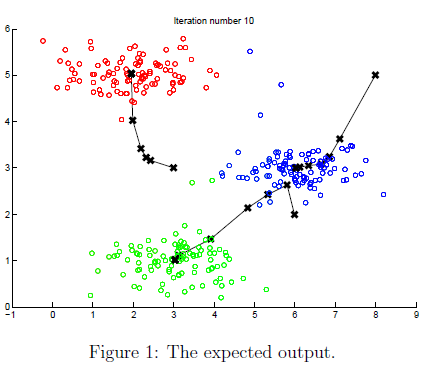

    When you run the next step, the *K*-means code will produce a visualization that steps you through the progress of the algorithm at each iteration. 

**At the command line**, **press enter multiple times to see how each step of the *****K*****-means algorithm changes the centroids and cluster assignments.** 

At the end, your figure should look as the one displayed in Figure 1.

% Load an example dataset
load('ex7data2.mat');
% Settings for running K-Means
max_iters = 10;

For consistency, here we set centroids to specific values but in practice you want to generate them automatically, such as by setting them to be random examples (as can be seen in `kMeansInitCentroids`).

initial_centroids = [3 3; 6 2; 8 5];

% Run K-Means algorithm. The 'true' at the end tells our function to plot the progress of K-Means
figure('visible','on'); hold on; 
plotProgresskMeans(X, initial_centroids, initial_centroids, idx, K, 1); 
xlabel('Press ENTER in command window to advance','FontWeight','bold','FontSize',14)
[~, ~] = runkMeans(X, initial_centroids, max_iters, true);
set(gcf,'visible','off'); hold off;

### 1.3 Random initialization

The initial assignments of centroids for the example dataset were designed so that you will see the same figure as in Figure 1. In practice, a good strategy for initializing the centroids is to select random examples from the training set. In this part of the exercise, you should complete the function `kMeansInitCentroids.m` with the following code:

The code above first randomly permutes the indices of the examples (using randperm). Then, it selects the first $K$ examples based on the random permutation of the indices. This allows the examples to be selected at random without the risk of selecting the same example twice.

*You do not need to make any submissions for this part of the exercise.*

### 1.4 Image compression with *K*-means

In this exercise, you will apply *K*-means to image compression. In a straightforward 24-bit color representation of an image, each pixel is represented as three 8-bit unsigned integers (ranging from 0 to 255) that specify the red, green and blue intensity values. This encoding is often refered to as the RGB encoding. Our image contains thousands of colors, and in this part of the exercise, you will reduce the number of colors to 16 colors. By making this reduction, it is possible to represent (compress) the photo in an efficient way. Specifically, you only need to store the RGB values of the 16 selected colors, and for each pixel in the image you now need to only store the index of the color at that location (where only 4 bits are necessary to represent 16 possibilities). 

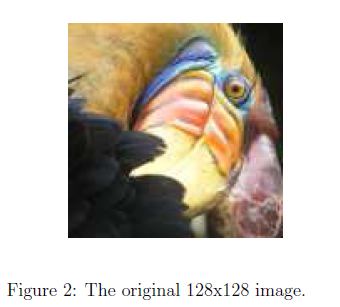

    In this exercise, you will use the *K*-means algorithm to select the 16 colors that will be used to represent the compressed image. Concretely, you will treat every pixel in the original image as a data example and use the *K*-means algorithm to find the 16 colors that best group (cluster) the pixels in the 3-dimensional RGB space. Once you have computed the cluster centroids on the image, you will then use the 16 colors to replace the pixels in the original image.

**The provided photo used in this exercise belongs to Frank Wouters and is used with his permission.*

#### 1.4.1 *K*-means on pixels

In MATLAB, images can be read in as follows:

This creates a three-dimensional matrix `A` whose first two indices identify a pixel position and whose last index represents red, green, or blue. For example, `A(50,33,3)` gives the blue intensity of the pixel at row 50 and column 33. The code below first loads the image, and then reshapes it to create an m by 3 matrix of pixel colors (where $m = 16384 = 128\times128$), and calls your *K*-means function on it.

%  Load an image of a bird
A = double(imread('bird_small.png'));
A = A / 255; % Divide by 255 so that all values are in the range 0 - 1

% Size of the image
img_size = size(A);

Reshape the image into an Nx3 matrix where N = number of pixels. Each row will contain the Red, Green and Blue pixel values. This gives us our dataset matrix X that we will use K-Means on.

X = reshape(A, img_size(1) * img_size(2), 3);

Run your K-Means algorithm on this data. You should try different values of K and max_iters here:

K = 16;
max_iters = 10;

When using K-Means, it is important the initialize the centroids randomly. You should complete the code in `kMeansInitCentroids.m` before proceeding

initial_centroids = kMeansInitCentroids(X, K);
% Run K-Means
[centroids, ~] = runkMeans(X, initial_centroids, max_iters);

    After finding the top $K = 16$ colors to represent the image, you can now assign each pixel position to its closest centroid using the `findClosestCentroids` function. This allows you to represent the original image using the centroid assignments of each pixel. Notice that you have signicantly reduced the number of bits that are required to describe the image. The original image required 24 bits for each one of the $128\times128$ pixel locations, resulting in total size of $128\times128\times24 = 393,216$ bits. 

    The new representation requires some overhead storage in form of a dictionary of 16 colors, each of which require 24 bits, but the image itself then only requires 4 bits per pixel location. The final number of bits used is therefore $16\times24 + 128\times128\times4 = 65,920$ bits, which corresponds to compressing the original image by about a factor of 6. 

% Find closest cluster members
idx = findClosestCentroids(X, centroids);

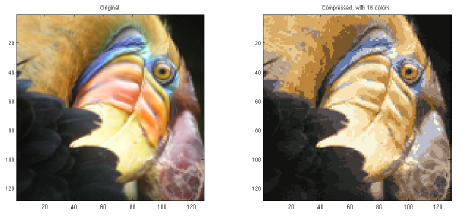

    Finally, you can view the effects of the compression by reconstructing the image based only on the centroid assignments. Specically, you can replace each pixel location with the mean of the centroid assigned to it. Figure 3 shows the reconstruction we obtained. Even though the resulting image retains most of the characteristics of the original, we also see some compression artifacts.

Essentially, now we have represented the image `X` as in terms of the indices in `idx`. We can now recover the image from the indices (`idx`) by mapping each pixel (specified by it's index in `idx`) to the centroid value.

X_recovered = centroids(idx,:);

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, img_size(1), img_size(2), 3);

% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));
axis square

*You do not need to make any submissions for this part of the exercise.*

### 1.5 Optional (ungraded) exercise: Use your own image

In this exercise, modify the code we have supplied to run on one of your own images. Note that if your image is very large, then *K*-means can take a long time to run. Therefore, we recommend that you resize your images to managable sizes before running the code. You can also try to vary `K` to see the effects on the compression.

## 2. Principal Component Analysis

In this exercise, you will use principal component analysis (PCA) to perform dimensionalty reduction. You will first experiment with an example 2D dataset to get intuition on how PCA works, and then use it on a bigger dataset of 5000 face image dataset. The code provided, will help you step through the first half of the exercise.

### 2.1 Example dataset

To help you understand how PCA works, you will first start with a 2D dataset which has one direction of large variation and one of smaller variation. The code below will plot the training data (Figure 4). 

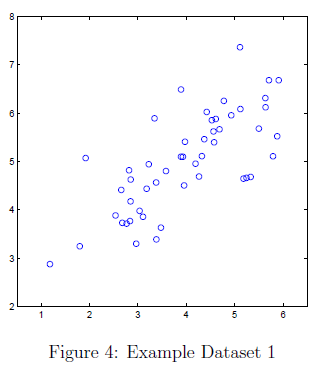

In this part of the exercise, you will visualize what happens when you use PCA to reduce the data from 2D to 1D. In practice, you might want to reduce data from 256 to 50 dimensions, say; but using lower dimensional data in this example allows us to visualize the algorithms better.

% Initialization
clear;
% The following command loads the dataset. You should now have the variable X in your environment
load ('ex7data1.mat');

% Visualize the example dataset
figure;
plot(X(:, 1), X(:, 2), 'bo');
axis([0.5 6.5 2 8]); axis square;

### 2.2 Implementing PCA

In this part of the exercise, you will implement PCA. PCA consists of two computational steps: First, you compute the covariance matrix of the data. Then, you use MATLAB's `svd` function to compute the eigenvectors $U_1, U_2,\ldots,U_n$. These will correspond to the principal components of variation in the data. Before using PCA, it is important to first normalize the data by subtracting the mean value of each feature from the dataset, and scaling each dimension so that they are in the same range. In the code below, this normalization has been performed for you using the `featureNormalize` function.

    After normalizing the data, you can run PCA to compute the principal components. You task is to complete the code in `pca.m` to compute the principal components of the dataset. First, you should compute the covariance matrix of the data, which is given by:


$$\Sigma =\frac{1}{m}X^T X$$


where $X$ is the data matrix with examples in rows, and $m$ is the number of examples. Note that $\Sigma$ is a $n \times n$ matrix and not the summation operator.

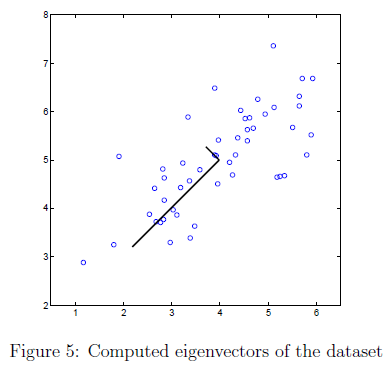

After computing the covariance matrix, you can run SVD on it to compute the principal components. In MATLAB, you can run SVD with the following command: 

where `U` will contain the principal components and `S` will contain a diagonal matrix. Once you have completed `pca.m`, the code below will run PCA on the example dataset and plot the corresponding principal components found (Figure 5). The script will also output the top principal component (eigenvector) found, and you should expect to see an output of about `[-0.707 -0.707]`. (It is possible that MATLAB may instead output the negative of this, since $U_1$ and $-U_1$ are equally valid choices for the first principal component.)

% Before running PCA, it is important to first normalize X
[X_norm, mu, ~] = featureNormalize(X);

% Run PCA
[U, S] = pca(X_norm);

% Draw the eigenvectors centered at mean of data. These lines show the directions of maximum variations in the dataset.
hold on;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', '-k', 'LineWidth', 2);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', '-k', 'LineWidth', 2);
hold off;

fprintf('Top eigenvector U(:,1) = %f %f \n', U(1,1), U(2,1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Dimensionality reduction with PCA

After computing the principal components, you can use them to reduce the feature dimension of your dataset by projecting each example onto a lower dimensional space, $x^{(i)}\rightarrow z^{(i)}$ (e.g., projecting the data from 2D to 1D). In this part of the exercise, you will use the eigenvectors returned by PCA and project the example dataset into a 1-dimensional space.

    In practice, if you were using a learning algorithm such as linear regression or perhaps neural networks, you could now use the projected data instead of the original data. By using the projected data, you can train your model faster as there are less dimensions in the input.

#### 2.3.1 Projecting the data onto the principal components

You should now complete the code in `projectData.m`. Specically, you are given a dataset `X`, the principal components `U`, and the desired number of dimensions to reduce to `K`. You should project each example in `X` onto the top `K` components in `U`. Note that the top `K` components in `U` are given by the first `K` columns of `U`, that is `U_reduce = U(:, 1:K)`.

Once you have completed the code in` projectData.m`, run the code below to project the first example onto the first dimension and you should see a value of about `1.481` (or possibly `-1.481`, if you got $-U_1$ instead of $U_1$).

% Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
fprintf('Projection of the first example: %f\n', Z(1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.2 Reconstructing an approximation of the data

After projecting the data onto the lower dimensional space, you can approximately recover the data by projecting them back onto the original high dimensional space. Your task is to complete `recoverData.m` to project each example in `Z` back onto the original space and return the recovered approximation in `X_rec`. Once you have completed the code in `recoverData.m`, the code below will recover an approximation of the first example and you should see a value of about `[-1.047 -1.047]`.

X_rec  = recoverData(Z, U, K);
fprintf('Approximation of the first example: %f %f\n', X_rec(1, 1), X_rec(1, 2));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.3 Visualizing the projections

After completing both `projectData` and `recoverData`, the code in this section will perform both the projection and approximate reconstruction to show how the projection affects the data. In Figure 6, the original data points are indicated with the blue circles, while the projected data points are indicated with the red circles. The projection effectively only retains the information in the direction given by $U_1$.

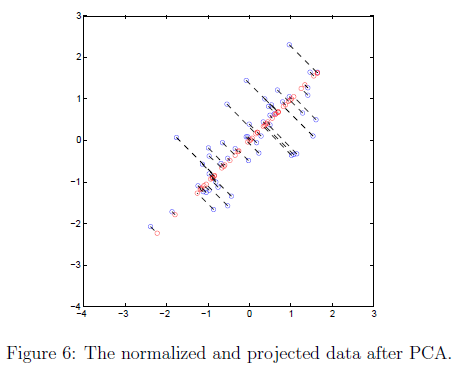

%  Plot the normalized dataset (returned from pca)
plot(X_norm(:, 1), X_norm(:, 2), 'bo');
axis([-4 3 -4 3]); axis square
%  Draw lines connecting the projected points to the original points
hold on;
plot(X_rec(:, 1), X_rec(:, 2), 'ro');
for i = 1:size(X_norm, 1)
    drawLine(X_norm(i,:), X_rec(i,:), '--k', 'LineWidth', 1);
end
hold off

### 2.4 Face image dataset

In this part of the exercise, you will run PCA on face images to see how it can be used in practice for dimension reduction. The dataset `ex7faces.mat` contains a dataset* `X` of face images, each $32 \times 32$ in grayscale. 

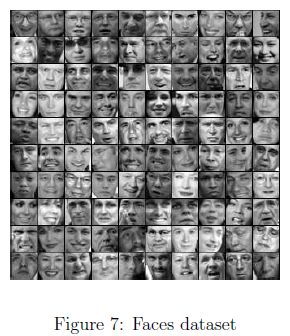

Each row of `X` corresponds to one face image (a row vector of length 1024). The code in this section will load and visualize the first 100 of these face images (Figure 7).

%  Load Face dataset
load ('ex7faces.mat')
%  Display the first 100 faces in the dataset
close all;
displayData(X(1:100, :));

**This dataset was based on a cropped version of the*[ *labeled faces in the wild dataset*](http://vis-www.cs.umass.edu/lfw/)*.*

#### 2.4.1 PCA on faces

To run PCA on the face dataset, we first normalize the dataset by subtracting the mean of each feature from the data matrix `X`. The code below will do this for you and then run your PCA code. After running PCA, you will obtain the principal components of the dataset. Notice that each principal component in `U` (each row) is a vector of length $n$ (where for the face dataset, $n = 1024$). It turns out that we can visualize these principal components by reshaping each of them into a $32 \times 32$ matrix that corresponds to the pixels in the original dataset. 

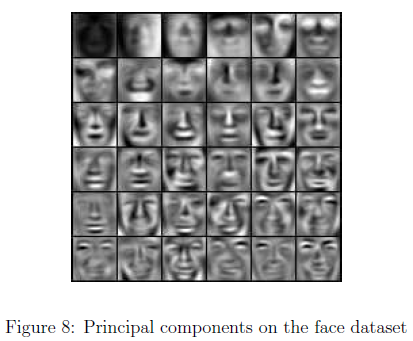

The code below displays the first 36 principal components that describe the largest variations (Figure 8).  If you want, you can also change the code to display more principal components to see how they capture more and more details. Before running PCA, it is important to first normalize `X` by subtracting the mean value from each feature.

[X_norm, ~, ~] = featureNormalize(X);

% Run PCA
[U, ~] = pca(X_norm);

% Visualize the top 36 eigenvectors found
displayData(U(:, 1:36)');

The code below will project the face dataset onto only the first 100 principal components. Concretely, each face image is now described by a vector $z^{(i)}\in\mathbb{R}^{100}$. 

K = 100;
Z = projectData(X_norm, U, K);

fprintf('The projected data Z has a size of: %d x %d', size(Z));

To understand what is lost in the dimension reduction, you can recover the data using only the projected dataset. In the code below, an approximate recovery of the data is performed and the original and projected face images are displayed side by side (Figure 9). 

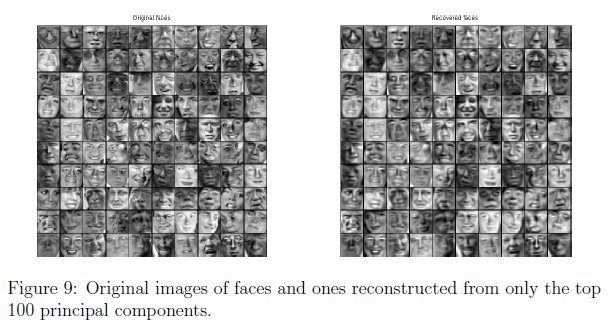

From the reconstruction, you can observe that the general structure and appearance of the face are kept while the fine details are lost. This is a remarkable reduction (more than $10\times$) in the dataset size that can help speed up your learning algorithm signicantly. For example, if you were training a neural network to perform person recognition (gven a face image, predict the identitfy of the person), you can use the dimension reduced input of only a 100 dimensions instead of the original pixels.

X_rec  = recoverData(Z, U, K);

% Display normalized data
subplot(1, 2, 1);
displayData(X_norm(1:100,:));
title('Original faces');
axis square;

% Display reconstructed data from only k eigenfaces
subplot(1, 2, 2);
displayData(X_rec(1:100,:));
title('Recovered faces');
axis square;

### 2.5 Optional (ungraded) exercise: PCA for visualization

In the earlier *K*-means image compression exercise, you used the *K*-means algorithm in the 3-dimensional RGB space. In this section, we have provided code to visualize the final pixel assignments in this 3D space using the `scatter3` function. Each data point is colored according to the cluster it has been assigned to. You can select the rotate icon and then drag your mouse on the figure to rotate and inspect this data in 3 dimensions.

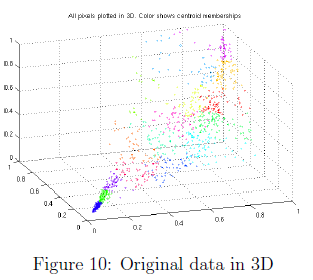

clear;
% Re-load the image from the previous exercise and run K-Means on it
% For this to work, you need to complete the K-Means assignment first
A = double(imread('bird_small.png'));
A = A / 255;
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16; 
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

%  Sample 1000 random indexes (since working with all the data is
%  too expensive. If you have a fast computer, you may increase this.
sel = floor(rand(1000, 1) * size(X, 1)) + 1;

%  Setup Color Palette
palette = hsv(K);
colors = palette(idx(sel), :);

%  Visualize the data and centroid memberships in 3D
figure;
scatter3(X(sel, 1), X(sel, 2), X(sel, 3), 10, colors);
title('Pixel dataset plotted in 3D. Color shows centroid memberships');

    It turns out that visualizing datasets in 3 dimensions or greater can be cumbersome. Therefore, it is often desirable to only display the data in 2D even at the cost of losing some information. In practice, PCA is often used to reduce the dimensionality of data for visualization purposes. In the code below, the script will apply your implementation of PCA to the 3-dimensional data to reduce it to 2 dimensions and visualize the result in a 2D scatter plot. The PCA projection can be thought of as a rotation that selects the view that maximizes the spread of the data, which often corresponds to the 'best' view.

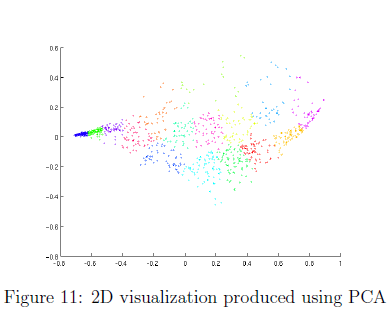

% Subtract the mean to use PCA
[X_norm, mu, sigma] = featureNormalize(X);

% PCA and project the data to 2D
[U, S] = pca(X_norm);
Z = projectData(X_norm, U, 2);

% Plot in 2D
figure;
plotDataPoints(Z(sel, :), idx(sel), K);
title('Pixel dataset plotted in 2D, using PCA for dimensionality reduction');

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored. 

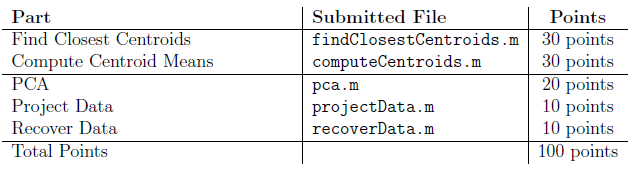

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.